p1 = rand([3 1])*10;
p2 = rand([3 1])*10;
k = rand([3 1]);
k = k/norm(k);
theta = rand*2*pi-pi

theta = -0.2675


d = norm(p2-rot(k,theta)*p1);

norm(p2-rot(k,theta)*p1) - d

ans = 0


t_a = fixed_subproblem3(p1,p2,k,d)

t_a =     2.0554
   -0.2675


wrapToPi(t_a)

ans =     2.0554
   -0.2675



norm(p2-rot(k,t_a(1))*p1) - d

ans = -8.8818e-16

norm(p2-rot(k,t_a(2))*p1) - d

ans = -8.8818e-16

t_b = subproblem3_linear(p1,p2,k,d)

t_b =    -0.2675    2.0554



norm(p2-rot(k,t_b(1))*p1) - d

ans = 8.8818e-16

norm(p2-rot(k,t_b(2))*p1) - d

ans = 0

N_trials = 10000

N_trials = 10000

N_attempts = 100

N_attempts = 100

T_orig = [];
T_linear = [];

for i = 1:N_trials
    p1 = rand([3 1])*10;
    p2 = rand([3 1])*10;
    k = rand([3 1]);
    k = k/norm(k);
    theta = rand*2*pi-pi;
    
    d = norm(p2-rot(k,theta)*p1);
    
    tic;
    for j = 1:N_attempts
    t = fixed_subproblem3(p1,p2,k,d);
    end
    t = toc;
    T_orig = [T_orig t/N_attempts];

    tic
    for j = 1:N_attempts
    t = subproblem3_linear(p1,p2,k,d);
    end
    t = toc;
    T_linear = [T_linear t/N_attempts];
end

T_linear = rmoutliers(T_linear);
T_orig = rmoutliers(T_orig);

mean(T_orig)

ans = 3.9258e-06

mean(T_linear)

ans = 3.4108e-06


mean(T_orig)/mean(T_linear)

ans = 1.1510

mean(T_linear)/mean(T_orig)

ans = 0.8688

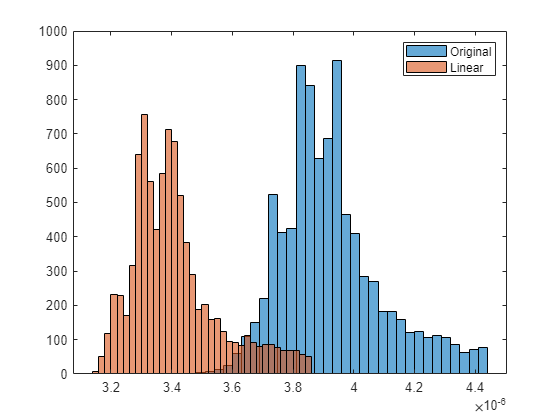


histogram(T_orig); hold on
histogram(T_linear); hold off
legend("Original", "Linear")